clear;clc;
[y, fs] = audioread("mhint_01_01.wav");

snr = [-5, -3, -1, 1, 3, 5];
[signal] = deal(zeros(length(y), length(snr)));
for i = 1:length(snr)
    signal(:,i) = awgn(y ,snr(i));
    signal(:,i) = signal(:,i) * norm(y) / norm(signal(:,i));
    str = "mhint_01_01_"+i+".wav";
    audiowrite(str, signal(:,i), fs);
end

score = [0 0 0 0 0 0];
score(1) =  pesq('mhint_01_01.wav', 'mhint_01_01_1.wav')

score =     1.0805         0         0         0         0         0


score(2) =  pesq('mhint_01_01.wav', 'mhint_01_01_2.wav')

score =     1.0805    1.0695         0         0         0         0


score(3) =  pesq('mhint_01_01.wav', 'mhint_01_01_3.wav')

score =     1.0805    1.0695    1.0688         0         0         0


score(4) =  pesq('mhint_01_01.wav', 'mhint_01_01_4.wav')

score =     1.0805    1.0695    1.0688    1.0694         0         0


score(5) =  pesq('mhint_01_01.wav', 'mhint_01_01_5.wav')

score =     1.0805    1.0695    1.0688    1.0694    1.1240         0


score(6) =  pesq('mhint_01_01.wav', 'mhint_01_01_6.wav')

score =     1.0805    1.0695    1.0688    1.0694    1.1240    1.0676


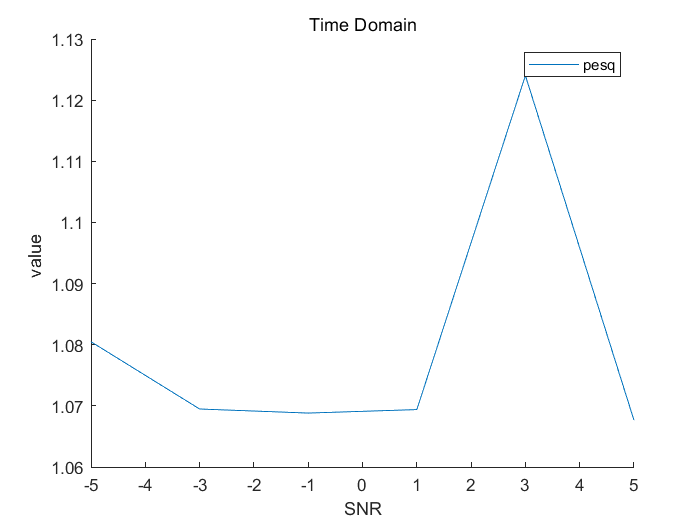

figure, hold on
plot(snr,score)
    legend("pesq")
    xlabel("SNR")
    ylabel("value "), title("Time Domain");
hold off